

%% Aircraft component weight equations
% Units: lb, ft, ft^2, gal, ft^3, inches where stated. Angles in DEGREES.
% NaN = value you still need to fill in. Values given in the nomenclature
% (e.g. K factors) are set to their "otherwise" default of 1.0 - change as needed.
clear; clc;

% ------------------------------------------------------------------------
%  VARIABLES
%  ------------------------------------------------------------------------


% --- Crew / payload ---
N_c         = 8;   % Number of crew
N_p         = 158;   % Total number of persons onboard (crew + passengers)
N_seat_E    = 90;   % Number of seats of given type
N_seat_PE   = 36;   % Number of seats of given type
N_seat_B    = 24;   % Number of seats of given type

% values from other code -------------------------------------------- [edit here]
xacw = 29.4; % longitudinal position of the aerodynamic centre of the wing from the nose [m] [guess]
xach = 51.4+4.834; % longitudinal position of the aerodynamic centre of the H-tail from the nose [m] [guess]
xacv = 51.4+6.625 ;    %longitudinal position of the aerodynamic centre of the V-tail from the nose [m] [guess]

%wing
MAC = 7.3376;
b = 64.977;
%H-stab
V_h = 1;
%V-stab
V_v = 0.09;

% --- Geometry: wing ---
AR          = 10;   % Wing aspect ratio
Bw          = 3.281*b;   % Wing span (ft)
Sw          = (3.281)^2*422.199;   % Reference wing area (ft^2) [u sure?]
Sw_m2 = 422.199; % Reference wing area
disp("Sw = "+ (Bw.^2)./(AR.*((3.281)^2))) % test

Sw = 422.2011


Scsw        = (3.281)^2*47.44;   % Area of wing mounted control surfaces (ft^2)
lambda      = 0.2325;   % Wing taper ratio
Lambda_w    = 32.42;   % Wing quarter chord sweep (deg)
tc_root     = 0.14;   % (t/c)_root, wing root thickness to chord ratio

% --- Geometry: horizontal tail ---

S_ht        = (3.281)^2*(V_h*Sw_m2*MAC)./(xach-xacw);   % Horizontal tailplane area (ft^2) [guess]
AR_h        = 4;   % Horizontal tailplane aspect ratio [edit]
B_t         = sqrt(AR_h*S_ht);   % Horizontal tailplane span (ft) [guess]
S_e         = 23.75*(3.281)^2;   % Elevator area (ft^2) [guess]
Lambda_ht   = Lambda_w+5;   % Horizontal tailplane quarter chord sweep (deg)
L_ht        = 3.281*(xach-xacw);   % Length from wing a.c. to horizontal tail a.c. (ft) [guess - edit]
Ht_Hv       = 0;   % Horizontal tail location on vertical tail (0.0 fuselage mounted, 1.0 T-tail)

% --- Geometry: vertical tail ---
AR_v        = 1.7;   % Vertical tailplane aspect ratio
S_vt        = (3.281)^2*(V_v*Sw_m2*b)./(xacv-xacw);   % Vertical tailplane area (ft^2)
B_Vt         = sqrt(AR_v*S_vt);   % Horiziontal tailplane span (ft) [guess]
Lambda_vt   = 40;   % Vertical tailplane quarter chord sweep (deg)
L_vt        = 3.281*(xacv-xacw);   % Length from wing a.c. to vertical tail a.c. (ft) [guess - edit]
tc_root_v   = 0.11;   % (t/c)_root_v, vertical tail root thickness to chord ratio [needs to be determined properly----]

% --- Geometry: fuselage / nacelle ---
D           = 5.9063; % Maximum fuselage diameter (m)
D_ft        = 3.281*D;   % Maximum fuselage diameter (ft)
F_w         = 3.281*2.9;   % Fuselage width at horizontal tail intersection (ft) [guess]
L_f_m       = 63.191; % Total fuselage length (m)
x_tailcap_joint_m = 0.517;                % Tail-cap structural joint location (m) [confirmed]
x_radome_joint_m  = 1.795;                % Radome structural joint location (m) [confirmed]
L           = 3.281*(L_f_m- x_tailcap_joint_m - x_radome_joint_m);  % Fuselage structural length (ft) [confirmed]
L_f         = 3.281*L_f_m;   % Total fuselage length (ft)
S_f         = 3.281^2*1006.1;   % Fuselage wetted area (ft^2) [guess]
N_Lt        = 21.19;   % Nacelle length (ft)
N_w         = 10.96;   % Nacelle width (ft)
S_n         = 653;   % Nacelle wetted area (ft^2)
A_fc        = NaN;   % Cargo hold floor area (ft^2)
V_pr        = 3.281^3*1048.2;   % Volume of pressurized sections (ft^3) [estimate]

% --- Propulsion ---
N_en        = 2;   % Number of engines
L_ec        = 255.188;   % Engine controls routing distance, engine to cockpit - to tail if multiengine (ft)

% --- Fuel system ---
V_t         = 123.29*264.172;   % Total volume of fuel tanks (gal)
rho_f       = 775./16.018; %density of the fuel [lb/ft^3]
W_fuel      = rho_f*V_t./7.48; %weight of the fuel [lbs]
V_i         = V_t;   % Integral fuel tank volume (gal)
V_p         = 0;   % Self sealing tank volume (gal)
N_t         = 3;   % Total number of fuel tanks

% --- Weights ---
W_dg        = 2.20462*267609;   % Design gross weight (lb) [guess]
W_l         = W_dg-W_fuel*0.70;   % Landing design gross weight (lb) (assuming that we only have 30% of the total fuel left) [123]
W_en        = 7549*2.205;   % Engine weight (lb) (x2 as two engines)
W_APU       = 762;   % Uninstalled APU weight (lb)
W_c         = (40000+N_seat_B*35+N_seat_PE*28+N_seat_E*23)*2.205;   % Maximum cargo weight (lb)
W_pas       = 84*150*2.205; %maximum passenger weight (lb)
TW0         = 0.288;  % Thrust-to-weight ratio T/W0
W_uav       = 0.02*(W_dg*(0.32 + 0.66*W_dg^(-0.13)*AR^0.30*TW0^0.06*(W_dg/Sw)^(-0.05)*0.82^0.05)*1.0);   % Uninstalled avionics weight, typ. 800-1400 (lb)
W_seat_E    = 35*2.205;   % Weight of single economy seat (lb)
W_seat_PE   = 80*2.205;   % Weight of single premium economy seat (lb)
W_seat_B    = 175*2.205;   % Weight of single business class seat (lb)

% --- Load factors ---
N_z         = 1.5*2.5;   % Ultimate load factor = 1.5 x limit load factor
N_gear      = 3.0;   % Ratio of avg total main gear load on landing to max landing weight; typ. 2.7-3
N_l         = 1.5*N_gear;   % Ultimate landing gear load factor

% --- Landing gear ---
L_m         = 39.3701 * 2.5;   % Main landing gear length (in) [guess]
L_n         = 39.3701 * 2.5;   % Nose landing gear length (in) [guess]
N_mw        = 12;   % Number of main wheels
N_nw        = 2;   % Number of nose wheels
N_mss       = 2;   % Number of main gear shock struts
V_s         = 52.0304594092352*3.281;   % Landing stall speed (ft/s) 
 
% --- Controls / systems --- [123] 
N_f         = 7;   % Number of functions performed by controls; typ. 4-7
N_m         = 0;   % Number of mechanical functions performed by controls; typ. 0-2
S_cs        = (20.63+26.39+23.75+20.39)*3.281^2;   % Total control surface area (ft^2)
R_kva       = 400;   % System electrical rating; typ. 40-60 for transports (kVA)
L_a         = L_ec;   % Electrical routing distance, generators to avionics to cockpit (ft)
N_gen       = 4;  % Number of generators; typ. = N_en (+1?)

% --- Empirical K factors (defaults = 1.0 "otherwise" case) ---
K_buf       = 5.68;   % 1.02 short ranges; 5.68 very long ranges
K_door      = 1.18;   % 1.0 no cargo door; 1.06 one side door; 1.12 two side doors or aft clamshell; 1.25 two side + aft clamshell
K_lav       = 1.11;   % 1.11 long range; 0.31 short range; 3.9 business jets
K_Lg        = 1.0;   % 1.12 fuselage mounted landing gear; 1.0 otherwise
K_mp        = 1.0;   % 1.126 kneeling main gear; 1.0 otherwise
K_ng        = 1.0;   % 1.017 pylon mounted nacelle; 1.0 otherwise
K_np        = 1.0;   % 1.15 kneeling nose gear; 1.0 otherwise
K_r         = 1.0;   % 1.133 reciprocating engines; 1.0 otherwise
K_tp        = 1.0;   % 0.793 turboprop; 1.0 otherwise
K_uht       = 1.0;   % 1.143 all-moving tail; 1.0 otherwise
K_p         = 1.0;   % 1.4 engine with propeller; 1.0 otherwise
K_tr        = 1.0;   % 1.18 jet with thrust reversers; 1.0 otherwise

% --- Derived quantities from the nomenclature ---
K_ws        = 0.75*((1 + 2*lambda)/(1 + lambda))*Bw*tand(Lambda_w)/L;  % wing sweep factor
K_y         = 0.3*L_ht;          % Pitching radius of gyration (ft)
K_z         = L_vt;              % Yaw radius of gyration (ft)
I_y         = W_dg*K_y^2;        % Pitching moment of inertia (lb ft^2), W_o ~ W_dg
W_enc       = 2.331*K_p*K_tr*W_en^0.901;  % Weight of engine and contents (lb)

% --- Material Factors ---

% wing
MF_w = 0.78;

% tail plane
MF_tp = 0.75;

% fuselage/nacelle
MF_F = 0.85;

% Landing gear
MF_lg = 0.88;

% ------------------------------------------------------------------------
%  WEIGHT EQUATIONS
%  ------------------------------------------------------------------------

% Aircraft wings
W_w = (0.0051 * (W_dg*N_z)^0.557 * Sw^0.649 * AR^0.5 * (1 + lambda)^0.1 * Scsw^0.1) ...
      ./ (cosd(Lambda_w) * tc_root^0.4);
W_w = MF_w*W_w; % Fudge factor for composites (from raymer)

% Horizontal tail plane
W_ht = (0.0379 * K_uht * W_dg^0.639 * N_z^0.1 * S_ht^0.75 * K_y^0.704 * AR_h^0.166 ...
       * (1 + S_e/S_ht)^0.1) ...
       ./ ((1 + F_w/B_t)^0.25 * L_ht * cosd(Lambda_ht));
W_ht = MF_tp*W_ht; % Fudge factor for composites (from raymer)

% Vertical tail plane
W_vt = (0.0026 * (1 + Ht_Hv)^0.225 * W_dg^0.556 * N_z^0.536 * S_vt^0.5 * K_z^0.875 * AR_v^0.35) ...
       ./ (L_vt^0.5 * cosd(Lambda_vt) * tc_root_v^0.5);
W_vt = MF_tp*W_vt; % Fudge factor for composites (from raymer)

% Fuselage
W_fus = 0.3280 * K_door * K_Lg * (W_dg*N_z)^0.5 * L^0.25 * S_f^0.302 * (1 + K_ws)^0.04 * (L/D_ft)^0.1;
W_fus = MF_F*W_fus; % Fudge factor for composites (from raymer)

% Main landing gear
W_mlg = 0.0106 * K_mp * W_l^0.888 * N_l^0.25 * L_m^0.4 * N_mw^0.321 * V_s^0.1 / N_mss^0.5;
W_mlg = MF_lg*W_mlg; % Fudge factor for composites (from raymer)

% Nose landing gear
W_nlg = 0.032 * K_np * W_l^0.646 * N_l^0.2 * L_n^0.5 * N_nw^0.45;
W_nlg = MF_lg*W_nlg; % Fudge factor for composites (from raymer)

% Nacelle
W_inl = 0.6724 * K_ng * N_Lt^0.1 * N_w^0.294 * N_z^0.119 * W_enc^0.611 * N_en^0.984 * S_n^0.224;
W_inl = MF_F*W_inl; % Fudge factor for composites (from raymer)

% Engine controls
W_ec = 5*N_en + 0.8*L_ec;

% Engine (pneumatic) starter
W_es = 49.19 * (N_en*W_en/1e3)^0.541;

% Fuel system
W_fs = 2.405 * V_t^0.606 * N_t^0.5 * (1 + V_p/V_t) / (1 + V_i/V_t);

% Flight controls
W_fc = 145.9 * N_f^0.554 * S_cs^0.2 * (I_y*1e-6)^0.07 / (1 + N_m/N_f);

% Installed APU
W_APUinst = 2.2*W_APU;

% Instruments
W_instr = 4.509 * K_r * K_tp * N_c^0.541 * N_en * (L_f + Bw)^0.5;

% Hydraulic system
W_hydr = 0.2673 * N_f * (L_f + Bw)^0.937;

% Electrical system
W_el = 7.291 * R_kva^0.782 * L_a^0.346 * N_gen^0.1;

% Avionics
W_av = 1.73 * W_uav^0.983;

% Furnishings
W_furn = 0.0577 * N_c^0.1 * W_c^0.393 * S_f^0.75 + N_seat_E*W_seat_E + N_seat_PE*W_seat_PE + N_seat_B*W_seat_B + K_lav*N_p^1.33 + K_buf*N_p^1.12;

% Air-conditioning
W_ac = 62.36 * N_p^0.25 * (V_pr*1e-3)^0.604 * W_uav^0.1;

% Anti-icing system
W_ai = 0.002*W_dg;

% Handling gear (civilian)
W_hg = 3.0e-4*W_dg;

% Handling gear (military transport) - use instead of the civilian line above
% W_hg = 2.4*A_fc;

% OTHER WEIGHTS


% ------------------------------------------------------------------------
%  SUMMARY
%  ------------------------------------------------------------------------
names   = {'Wing','Horizontal tail','Vertical tail','Fuselage','Main landing gear', ...
           'Nose landing gear','Nacelle','Engine controls','Engine starter','Fuel system', ...
           'Flight controls','Installed APU','Instruments','Hydraulics','Electrical', ...
           'Avionics','Furnishings','Air-conditioning','Anti-icing','Handling gear','Engines'};
weights = [W_w W_ht W_vt W_fus W_mlg W_nlg W_inl W_ec W_es W_fs W_fc W_APUinst ...
           W_instr W_hydr W_el W_av W_furn W_ac W_ai W_hg,W_en*2];
weights_kg = weights./2.205; %weight in kg

T = table(names', weights',weights_kg', 'VariableNames', {'Dry Component','Weight_lb','weight_kg'});
disp(T);

        Dry Component        Weight_lb    weight_kg
    _____________________    _________    _________

    {'Wing'             }      50410        22862  
    {'Horizontal tail'  }     5890.1       2671.2  
    {'Vertical tail'    }     5077.9       2302.9  
    {'Fuselage'         }      39149        17755  
    {'Main landing gear'}      23070        10462  
    {'Nose landing gear'}     2288.5       1037.9  
    {'Nacelle'          }     5481.1       2485.8  
    {'Engine controls'  }     214.15        97.12  
    {'Engine starter'   }     327.68       148.61  
    {'Fuel system'      }     1130.9       512.86  
    {'Flight controls'  }     2591.9       1175.5  
    {'Installed APU'    }     1676.4       760.27  
    {'Instruments'      }     569.61       258.32  
    {'Hydraulics'       }     537.75       243.88  
    {'Electrical'       }     6174.2       2800.1  
    {'Avionic

fprintf('Total of listed components (dry): %.1f lb\n', sum(weights));

Total of listed components (dry): 224509.3 lb


fprintf('Total of listed components (dry): %.1f tn\n', sum(weights)/2205);

Total of listed components (dry): 101.8 tn



name2 = {'Fuel','Cargo','Passengers'};
weight2 = [W_fuel,W_c,W_pas];
weight2_kg  = weight2./2.205;

T2 = table(name2', weight2',weight2_kg', 'VariableNames', {'Component','Weight_lb','weight_kg'});
disp(T2);

      Component       Weight_lb     weight_kg
    ______________    __________    _________

    {'Fuel'      }    2.1067e+05      95543  
    {'Cargo'     }         96839      43918  
    {'Passengers'}         27783      12600  



fprintf('Total of listed components: %.1f lb\n', sum(weight2));

Total of listed components: 335294.0 lb


fprintf('Total of listed components: %.1f tn\n', sum(weight2)/2205);

Total of listed components: 152.1 tn



fprintf('Total of listed components total: %.1f lb\n', sum(weight2)+sum(weights));

Total of listed components total: 559803.3 lb


fprintf('Total of listed components total: %.1f tn\n', (sum(weight2)+sum(weights))/2205);

Total of listed components total: 253.9 tn





% NOW the location of the centre of gravity determination

% To define an axis, the x shall be the longitudinal distance from the nose, heading to the tail of the aircraft
% The z axis for now shall denote the distance from the geometric centre of
% the fuselage (later will be cg) with upward as positive z
% The y axis shall be defined as the distance from the geometric centre-line of the aircraft with the right side being positive


% ------------------------------------------------------------------------
%  LOCATION OF WEIGHTS for CG
%  ------------------------------------------------------------------------

% Aircraft wings
xW_w = xacw+1.8225; 
zW_w = -0.4*D;   % low wing: roughly -2.0 to -2.5 m for D of 6 m[guess]

% Horizontal tail plane
xW_ht = xach+1.0;% [guess -edit this]
zW_ht = 0.5*D; % mounted on the rear fuselage, about +0.5 to +1.0 m[guess]

% Vertical tail plane
xW_vt = xach+1.0;% [guess -edit this]
zW_vt = 0.5*D + 0.35*B_Vt/3.281;% fuselage top plus about 35-40% of the fin span [guess]

% Fuselage ( from the CAD?)
xW_fus = 0.45*L_f_m;% [guess -raymer 0.4-0.5 but get it from the cad]
zW_fus = 0;% [guess - geometry]

% Main landing gear (deployed)
xW_mlg_dep = 32.42; % [guess]
H_gear = 3; % [guess]
zW_mlg_dep = -(0.5*D + 0.5*H_gear);  % H_gear is the strut + wheel height, about 3-4 m

% Main landing gear (retracted)
xW_mlg_ret = 32.42; % [guess -does this change?]
zW_mlg_ret = -0.5*D; % in the belly bay, about -2.5 to -3 m [guess]

% Nose landing gear (deployed)
xW_nlg_dep = 6; % [guess]
zW_nlg_dep = -(0.5*D + 0.4*H_gear);% [guess]

% Nose landing gear (retracted)
xW_nlg_ret = 6; % [guess]
zW_nlg_ret = -0.4*D;% inside the nose wheel well, about -2.0 to -2.4 m [guess]

%engine
xW_eng = xacw-3;% [guess - approx]
zW_eng = -0.35*D;% [guess - approx]

% Nacelle
xW_inl = xW_eng;% [guess - approx]
zW_inl = zW_eng;% [guess]

% Engine controls
xW_ec = xW_eng;% [guess - approx]
zW_ec = zW_eng;% [guess]

% Engine (pneumatic) starter
xW_es = xW_eng-0.1*3.5;% [guess]
zW_es = zW_eng-0.3*1.65;% [guess]

% Fuel system
xW_fs = xW_w;% [guess]
zW_fs = zW_w;% [guess]

% Flight controls
xW_fc = 0.5*(xW_w + xW_ht);% [guess -claude]
zW_fc = 0;% [guess]

% Installed APU
xW_APUinst = 0.92*L_f_m;  % in the tail cone [guess]
zW_APUinst = 0;% [guess]

% Instruments
xW_instr = 0.07*L_f_m;% cockpit [guess]
zW_instr = 0.1*D;  % about +0.6 m (the panel is above the centreline) [guess]

% Hydraulic system
xW_hydr = 0.5*(xW_w + xW_mlg_dep); % pumps and lines near the wing root / gear [guess]
zW_hydr = -0.3*D;% [guess]

% Electrical system
xW_el = 0.40*L_f_m;  % distributed, so use about 40-45% of L_f [guess]
zW_el = -0.1*D;% [guess]

% Avionics
xW_av = 0.07*L_f_m;  % mostly the avionics bay below the cockpit (nose) [guess]
zW_av = -0.2*D;    % [guess]

% Furnishings
xW_furn = 8.75+25.829./2; % seats, galleys and toilets run along the cabin (centred at about 50%) [guess]
zW_furn = 0.1*D;  % cabin floor sits about 0.3-0.5 m below the centreline, but the furnishings sit above it [guess]

% Air-conditioning
xW_ac = 0.45*L_f_m; % packs sit in the belly fairing under the wing box [guess]
zW_ac = -0.35*D;% [guess]

% Anti-icing system
xW_ai = xW_w;% [guess]
zW_ai = zW_w;% [guess]

% Handling gear (civilian)
xW_hg = 0.45*L_f_m; % handling gear: small, so put it with the fuselage[guess]
zW_hg = 0;% [guess]

% Outside of the Raymer equations

% Fuel

xW_Fuel = xW_w;% [guess]
zW_Fuel = zW_w;% [guess]

% Passengers
xW_Pass = 16.64+8.75;% [guess]
zW_Pass = -0.1;% [guess]

L_Wingbox = 10.5439;% wing box not 10.5439 but longer..

n_cargo_boxes = 62;
n_cargo_rows = n_cargo_boxes./2;

n_row_c_1 = 11;
n_row_c_2 = floor((xacw+0.25*MAC-L_Wingbox./2-8.75)./1.53416);
n_row_c_3 = n_cargo_rows-(n_row_c_2+n_row_c_1);

%Assume that the cargo is evenly distributed in the given space
c_cg_1 = (8.75+25.829+17.26./2).*(11/31);
c_cg_2 = (8.75+(xacw+0.25*MAC-L_Wingbox./2-8.75)./2).*(n_row_c_2/31);

x3_part_1 = xacw+0.25*MAC+L_Wingbox./2;
x3_part_2 = (L_f_m-10.041)-(xacw+0.25*MAC+L_Wingbox./2);
c_cg_3 = ((x3_part_1)+(x3_part_2./2)).*(n_row_c_3/31);

c_cg = c_cg_1+c_cg_2+c_cg_3;
%disp("c_cg = "+c_cg)

% Cargo
xW_Cargo = c_cg;% [guess]
zW_Cargo = -0.2756;% [guess]

%also we have to consider all the cases to make the plot

%
%% ========================================================================
%  CENTRE OF GRAVITY
%  ========================================================================
% Axes: x = metres from the nose (+aft), z = metres from the fuselage
% centre-line (+UP). Masses in kg.

lb2kg = 1/2.205;                 % same factor as used above
gear_down = false;                % true = gear deployed (take-off/landing), false = retracted (cruise) [vary]

% --- 1. Empty-weight components (Raymer build-up) -------------------------
if gear_down
    xW_mlg = xW_mlg_dep;  zW_mlg = zW_mlg_dep;
    xW_nlg = xW_nlg_dep;  zW_nlg = zW_nlg_dep;
else
    xW_mlg = xW_mlg_ret;  zW_mlg = zW_mlg_ret;
    xW_nlg = xW_nlg_ret;  zW_nlg = zW_nlg_ret;
end

% Same order as 'names' / 'weights' in the summary block
x_pos = [xW_w xW_ht xW_vt xW_fus xW_mlg xW_nlg xW_inl xW_ec xW_es xW_fs xW_fc ...
         xW_APUinst xW_instr xW_hydr xW_el xW_av xW_furn xW_ac xW_ai xW_hg xW_eng];
z_pos = [zW_w zW_ht zW_vt zW_fus zW_mlg zW_nlg zW_inl zW_ec zW_es zW_fs zW_fc ...
         zW_APUinst zW_instr zW_hydr zW_el zW_av zW_furn zW_ac zW_ai zW_hg zW_eng];
m_comp = weights*lb2kg;          % kg (includes the engines)

assert(numel(x_pos) == numel(m_comp) && numel(z_pos) == numel(m_comp), ...
       'Position vectors and weights vector must be the same length');
assert(~any(isnan([x_pos z_pos m_comp])), 'A position or weight is still NaN');

M_empty = sum(m_comp);
x_empty = sum(m_comp.*x_pos)/M_empty;
z_empty = sum(m_comp.*z_pos)/M_empty;

Tcg = table(names', m_comp', x_pos', z_pos', (m_comp.*x_pos)', ...
            'VariableNames', {'Component','Mass_kg','x_m','z_m','Moment_x_kgm'});
disp(Tcg);

          Component          Mass_kg     x_m        z_m       Moment_x_kgm
    _____________________    _______    ______    ________    ____________

    {'Wing'             }     22862     31.223     -2.3625      7.138e+05 
    {'Horizontal tail'  }    2671.2     57.234      2.9531     1.5289e+05 
    {'Vertical tail'    }    2302.9     57.234      7.1913      1.318e+05 
    {'Fuselage'         }     17755     28.436           0     5.0487e+05 
    {'Main landing gear'}     10462      32.42     -2.9531     3.3919e+05 
    {'Nose landing gear'}    1037.9          6     -2.3625         6227.3 
    {'Nacelle'          }    2485.8       26.4     -2.0672          65624 
    {'Engine controls'  }     97.12       26.4     -2.0672           2564 
    {'Engine starter'   }    148.61      26.05     -2.5622         3871.3 
    


% --- 2. Crew, passengers, cargo, fuel --------------------------------------
n_fd    = 2;                                   % flight-deck crew [guess]
m_crew  = N_c*84;                              % kg (84 kg per person, as used for W_uav)
x_crew  = (n_fd*xW_instr + (N_c-n_fd)*xW_furn)/N_c;   % 2 in the cockpit, rest in the cabin [guess]
z_crew  = (n_fd*zW_instr + (N_c-n_fd)*zW_Pass)/N_c;

m_pass  = (N_p - N_c)*84;                      % kg
x_pass  = xW_Pass;   z_pass = zW_Pass;

m_cargo = W_c*lb2kg;                           % kg (includes baggage)
x_cargo = xW_Cargo;  z_cargo = zW_Cargo;

m_fuel  = W_fuel*lb2kg;                        % kg, full tanks
x_fuel  = xW_Fuel;   z_fuel = zW_Fuel;

% Operating empty weight = empty components + crew
M_oew = M_empty + m_crew;
x_oew = (M_empty*x_empty + m_crew*x_crew)/M_oew;
z_oew = (M_empty*z_empty + m_crew*z_crew)/M_oew;

% Load items, in the order  OEW | cargo | passengers | fuel
lbl = {'OEW','Cargo','Passengers','Fuel'};
m_L = [M_oew, m_cargo, m_pass, m_fuel];
x_L = [x_oew, x_cargo, x_pass, x_fuel];
z_L = [z_oew, z_cargo, z_pass, z_fuel];

% --- 3. Loading cases -------------------------------------------------------
% each row: name, fraction of [OEW cargo passengers fuel] carried
cases = { 'OEW',                    [1 0 0 0];
          'OEW + cargo',            [1 1 0 0];
          'OEW + passengers',       [1 0 1 0];
          'OEW + pax + cargo',      [1 1 1 0];
          'OEW + fuel',             [1 0 0 1];
          'Max take-off (all)',     [1 1 1 1];
          'Landing (30% fuel)',     [1 1 1 0.3] };
nC  = size(cases,1);
M_c = zeros(nC,1);  x_c = zeros(nC,1);  z_c = zeros(nC,1);
for k = 1:nC
    mk     = cases{k,2}.*m_L;
    M_c(k) = sum(mk);
    x_c(k) = sum(mk.*x_L)/M_c(k);
    z_c(k) = sum(mk.*z_L)/M_c(k);
end

LEMAC = xacw - 0.25*MAC;                 % MAC leading edge, from the nose [m]
pMAC  = 100*(x_c - LEMAC)/MAC;           % CG as % of MAC

Tc = table(cases(:,1), M_c/1e3, x_c, z_c, pMAC, ...
           'VariableNames', {'Case','Mass_t','x_cg_m','z_cg_m','x_cg_pctMAC'});
disp(Tc);

             Case             Mass_t    x_cg_m     z_cg_m     x_cg_pctMAC
    ______________________    ______    ______    ________    ___________

    {'OEW'               }    102.49    28.625     -1.0206      14.433   
    {'OEW + cargo'       }    146.41    30.389    -0.79715      38.475   
    {'OEW + passengers'  }    115.09    28.271    -0.91985      9.6072   
    {'OEW + pax + cargo' }    159.01    29.993    -0.74191      33.077   
    {'OEW + fuel'        }    198.03    29.878      -1.668      31.515   
    {'Max take-off (all)'}    254.55    30.454     -1.3502      39.368   
    {'Landing (30% fuel)'}    187.67     30.18    -0.98942      35.637   




fprintf('\nEmpty (components): %.1f t, x = %.2f m, z = %.2f m\n', M_empty/1e3, x_empty, z_empty);


Empty (components): 101.8 t, x = 28.70 m, z = -1.03 m


fprintf('OEW (with crew):    %.1f t, x = %.2f m (%.1f %% MAC)\n', M_oew/1e3, x_oew, 100*(x_oew-LEMAC)/MAC);

OEW (with crew):    102.5 t, x = 28.62 m (14.4 % MAC)


fprintf('Build-up MTOW %.1f t vs W_dg %.1f t  (%+.1f %%)\n', M_c(6)/1e3, W_dg*lb2kg/1e3, ...
        100*(M_c(6)/(W_dg*lb2kg) - 1));

Build-up MTOW 254.6 t vs W_dg 267.6 t  (-4.9 %)


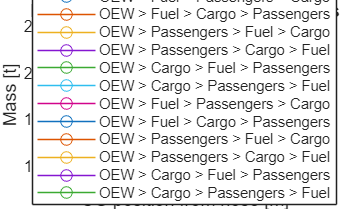


% --- Loading diagram plot -----------------------------------------------------
% every order of adding cargo / passengers / fuel to the OEW gives the CG envelope
figure (1); hold on; grid on;
P = perms(2:4);
for p = 1:size(P,1)
    idx = [1 P(p,:)];
    mc  = cumsum(m_L(idx));
    xc  = cumsum(m_L(idx).*x_L(idx))./mc;
    plot(xc, mc/1e3, '-o', 'DisplayName', strjoin(lbl(idx), ' > '));
end
xlabel('CG position from nose [m]'); ylabel('Mass [t]');
title('Loading diagram - all loading orders');
legend('Location','best');
hold off

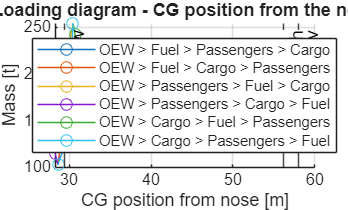


% second plot which has mass on the y and x pos from nose in m on the x
figure; hold on; grid on;
for p = 1:size(P,1)
    idx = [1 P(p,:)];
    mc  = cumsum(m_L(idx));
    xc  = cumsum(m_L(idx).*x_L(idx))./mc;      % CG after each item is added [m from nose]
    plot(xc, mc/1e3, '-o', 'DisplayName', strjoin(lbl(idx), ' > '));
end
xline(xacw,     '--k', 'X_acw', 'HandleVisibility', 'off');   
xline(xach, '--k', 'X_ach', 'HandleVisibility', 'off'); 
xline(xacv, '--k', 'X_acv', 'HandleVisibility', 'off'); 
xlabel('CG position from nose [m]'); ylabel('Mass [t]');
title('Loading diagram - CG position from the nose');
legend('Location','best');
hold off